# Prostatic Cancer Detection Algorithm

**Requirements: **

**Feeds into: **testingAlgorithm.m [Pending] 

**Saving All dicomImages in a Datastore**

Use makeimds function

[Missing Update makeimds filenames] 

% imds = makeimds(); 


Visualize a random selection of imds Images for Visualization

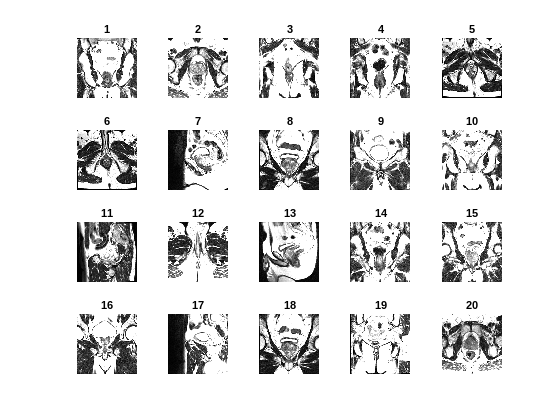

figure;
title('Random Selection of Loaded Images');
perm = randperm(1000,20);

for i = 1:20
    subplot(4,5,i);
    img = imread(imds.Files{perm(i)});
    %  [BW,img] = segmentImage(img)
    % This doesnt work but I do need to preprocess the images before
    % analysing them. 
    imshow(img)
    title(i)
end

### Label Count And Histogram 

figure;
countEachLabel(imds)

ans = 2×2 table
        Label         Count
    ______________    _____

    cancerImages       875 
    nocancerImages     557 


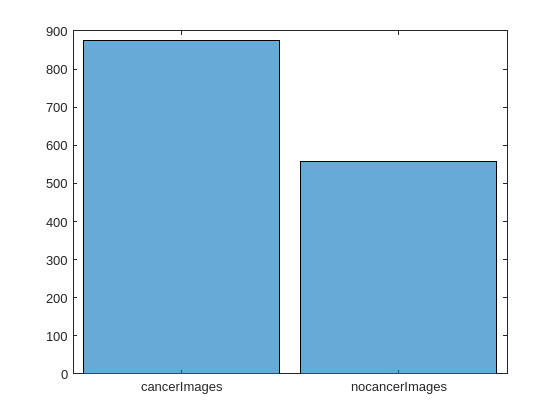

histogram (imds.Labels)

## Divide Data into Train, Validation and Testing Datasets 

 numTrainFiles = 400;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomized');

### Simple vs  Recursive DNN

inputSize = [256 256 1];
numClasses = 2;

%simple layers 
layers = [
    imageInputLayer(inputSize)
    convolution2dLayer(5,20)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

% layers = [
%     % Image Input layer
%     imageInputLayer(inputSize)
%     % Convolutional Layer
%     convolution2dLayer(3,8,'Padding','same')
%     batchNormalizationLayer
%     reluLayer
% 
%     maxPooling2dLayer(2,'Stride',2)
% 
%     convolution2dLayer(3,16,'Padding','same')
%     batchNormalizationLayer
%     reluLayer
% 
%     maxPooling2dLayer(2,'Stride',2)
% 
%     convolution2dLayer(3,32,'Padding','same')
%     batchNormalizationLayer
%     reluLayer
% 
%     fullyConnectedLayer(numClasses)
%     softmaxLayer
%     classificationLayer];

Training Options

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

Training Command 

net = trainNetwork(imdsTrain,layers,options);

% Use the algorithm to classify Validation DataSet
YPred = classify(net,imdsValidation)
% Sets YValidation Labels
YValidation = imdsValidation.Labels

Finds the Accuracy of the algorithm by comparing with the YValidation Labels

accuracy = mean(YPred == YValidation)